Purpose: Determining what neural activity is correlated with valence in subjects

clear all
cd('C:\Users\bgrau\Dropbox (Dartmouth College)\2023_Graul_EEE\Data\processed\sub-01\imgview')
load("imgview_freq_bpref.mat");


cfg = [];
% cfg.latency = [-1.5 4.5];
% cfg.channel = {'all', '-LTHA7'};
data = ft_selectdata(cfg, imgview_freq);

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

clearvars -except data imgview_freq
trlinfo = data.trialinfo;

First, we'll look at direct ratings of valence compared to neural activity in the frequency domain.

(Would an ERP be meaningful at all?)

design = [ones(height(trlinfo), 1), trlinfo.val_rating];
[n,p] = size(design);
design(1:10,:)

ans =     1.0000   78.1250
    1.0000   16.3411
    1.0000    8.4635
    1.0000   97.0703
    1.0000   31.4453
    1.0000    1.4974
    1.0000   48.4375
    1.0000    2.2135
    1.0000   88.6068
    1.0000  100.0000



% Normalize Design Matrix for comparison
design_norm = design;
for c = 1:p
    AVG = mean(design(:,c));
    STD = std(design(:,c),0,1);
        if abs(STD/AVG)<10*eps
            fprintf('confound %s is a constant \n', num2str(c));
        else
            design_norm(:,c) = (design(:,c) - AVG) / STD;
        end
    clear AVG STD;
end

confound 1 is a constant 


design_norm([1:10], :)

ans =     1.0000    0.7033
    1.0000   -0.9182
    1.0000   -1.1249
    1.0000    1.2005
    1.0000   -0.5218
    1.0000   -1.3077
    1.0000   -0.0758
    1.0000   -1.2889
    1.0000    0.9784
    1.0000    1.2774


Calculate the beta weights. Note that normalizing the design matrix makes a very large difference in our resulting beta weights. 

cfg = [];
cfg.confound = design;
cfg.output = 'beta';
cfg.statistics = 'yes';
cfg.normalize = 'no';

betas = ft_regressconfound_absfix(cfg, data);

the input is freq data with 121 channels, 28 frequencybins and 101 timebins
removing confound 1  2 
keeping confound  
skipping normalization procedure 
estimating the regression weights and removing the confounds 
performing statistics on the regression weights 
the call to "ft_regressconfound_absfix" took 1 seconds


bsize = size(betas.beta(1:p-1,:,:,:))

bsize =      1   121    28   101


d_factor = 1;

Let's correct for multiple comparisons using FDR correction. 

designp = reshape(betas.prob(2:p,:), [], 1);
[h, crit_p, adj_ci_cvrg, adj_p]=fdr_bh(designp,.05,'dep','yes');

Out of 342188 tests, 2227 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or dependent tests.


A note here about FDR: 

If 'pdep,' the original Bejnamini & Hochberg FDR procedure is used, which is guaranteed to be accurate if the individual tests are independent or positively dependent (e.g., Gaussian variables that are positively correlated or independent). 

If 'dep,' the FDR procedure described in Benjamini & Yekutieli (2001) that is guaranteed to be accurate for any test dependency structure (e.g., Gaussian variables with any covariance matrix) is used. 'dep' is always appropriate to use but is less powerful than 'pdep.'

NOTE: Maybe should test distribution of neural data?

Let's visualize the unthresholded and non-normalized values first. 


cfg = [];
cfg.avgoverrpt = 'yes'; % get the average activation across trials
mask_data = ft_selectdata(cfg, data);

the call to "ft_selectdata" took 0 seconds



betas.h = designp;
for i = 1:numel(betas.h)
    for cond = 1:p-1;
        if betas.h(i,cond) > 0.05
            betas.h(i,cond) = 0;
        else
            betas.h(i,cond) = 1;
        end
    end
end

betas.h = reshape(betas.h, bsize);

mask_p = squeeze(betas.h(d_factor, :,:,:));
sig_vox = sum(sum(sum(mask_p)))

sig_vox = 82634

fprintf('Unthresholded, non-normalized significant voxels: %d', sum(sum(sum(mask_p))))

Unthresholded, non-normalized significant voxels: 82634


for chan = 1:numel(mask_data.label)
    mask_data.mask(chan, :, :) = mask_data.powspctrm(chan, :, :) .* mask_p(chan,:,:);
end

mask_data.h1 = mask_p;
mask_data.h_log = mask_data.h1 > 0; % for outline

mask_data.b1 = squeeze(betas.beta(2,:,:,:));
mask_data.t1 = squeeze(betas.stat(2,:,:,:));


We need a cutoff for how many voxels on a given electrode is significant. 

Not sure how to determine this, so we're doing a bit of trial and error. 

Could do some sort of cluster analysis/correction, because just doing a number cutoff might mean missing really significant clumps if they're super localized

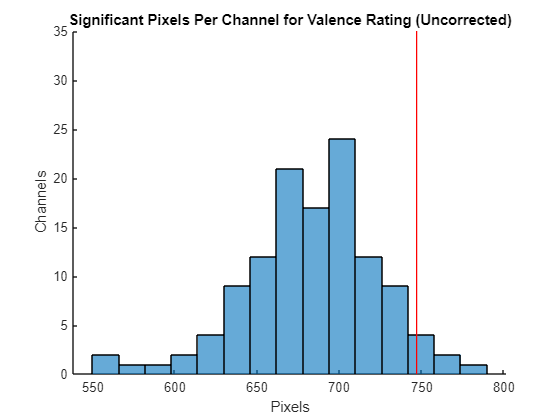

for i = 1:numel(mask_data.label)
    allchans(i,1) = sum(sum(mask_p(i,:,:)));
end
prct95 = prctile(allchans, 95);


figure; hold on;
histogram(allchans, 'NumBins', 15); 
line([prct95 prct95], [0 35], 'Color', 'red');

xlabel("Pixels")
ylabel("Channels")
title('Significant Pixels Per Channel for Valence Rating (Uncorrected)')
% fontsize(24, "points")
drawnow
hold off; 

Seems like most electrodes have some response, but it drops off around 700 or so.

c = 1;
sigchans = {};
for i = 1:numel(mask_data.label)
    channame = mask_data.label{i};
    if sum(sum(mask_p(i,:,:))) > prct95
    
        sigchans{c} = channame;
        c = c + 1;
    end
end
disp('Electrodes that survive')

Electrodes that survive


sigchans

sigchans = 1×5 cell array
    {'RPAG2-RPAG4'}    {'RTA2-RTA3'}    {'RTF7-RTF8'}    {'RIA8-RIA9'}    {'LTA9-LTA10'}


the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


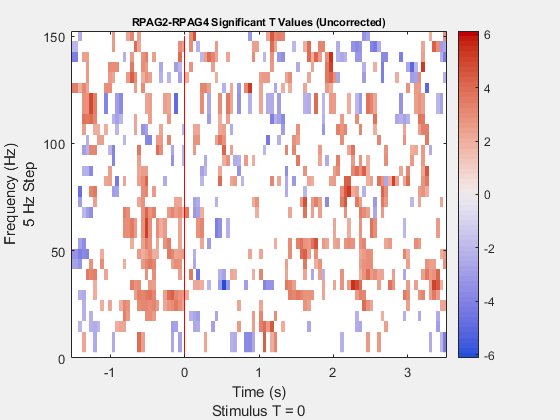

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


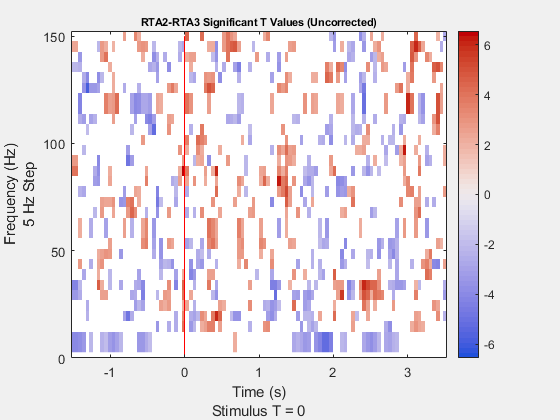

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


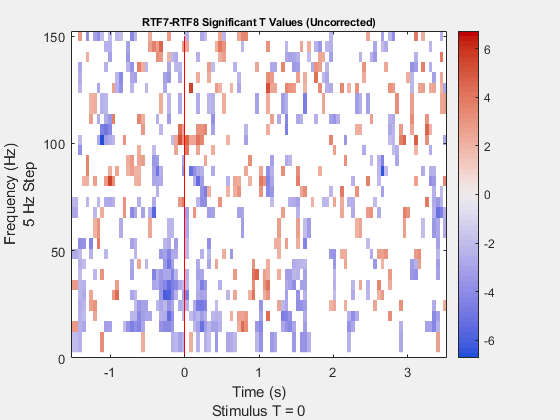

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


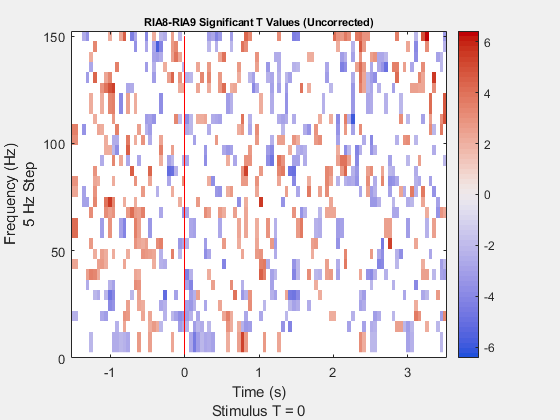

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


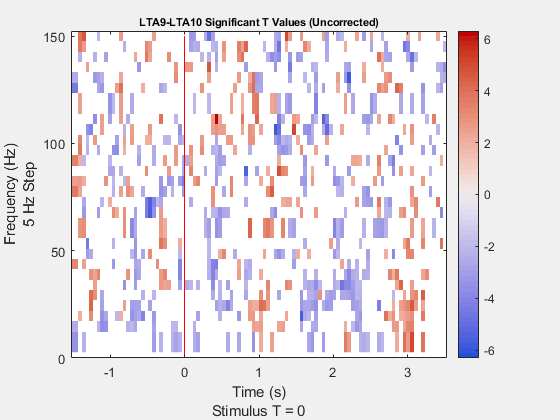

cfg = [];
for chan = 1:numel(sigchans)
    cfg.channel = sigchans{chan};    
    cfg.parameter = 't1';
    cfg.maskparameter = 'h1';
    cfg.colormap = 'coolwarm';
    cfg.figure = 'no';

    figure;
    set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, mask_data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title(sprintf('%s Significant T Values (Uncorrected)', cfg.channel))
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0

    drawnow
   hold off;
   clear a;

   pause(0.5)

end

Let's see what the FDR-corrected voxels look like in comparison

betas.adj_h = adj_p;
for i = 1:numel(adj_p)
    if adj_p(i, 1) > 0.05
        betas.adj_h(i, 1) = 0;
    else
        betas.adj_h(i, 1) = 1;
    end
end

betas.adj_h = reshape(betas.adj_h, bsize);

cfg = [];
cfg.avgoverrpt = 'yes'; % get the average activation across trials
mask_data_corr = ft_selectdata(cfg, data);


mask_p = squeeze(betas.adj_h(d_factor, :,:,:));
fprintf('Thresholded, non-normalized significant voxels: %d', sum(sum(sum(mask_p))))

for chan = 1:numel(mask_data.label)
    mask_data_corr.mask(chan, :, :) = mask_data.powspctrm(chan, :, :) .* mask_p(chan,:,:);
end

mask_data_corr.h = mask_p;
mask_data_corr.h_log = mask_data_corr.h > 0; % for outline

mask_data_corr.b1 = squeeze(betas.beta(2,:,:,:));
mask_data_corr.t1 = squeeze(betas.stat(2,:,:,:));


for i = 1:numel(mask_data.label)
    allchans(i,1) = sum(sum(mask_data_corr.h(i,:,:)));
end
prct95 = prctile(allchans, 95);

figure; hold on;

histogram(allchans, 'NumBins', 15); 
line([prct95 prct95], [0 30], 'Color', 'red');

xlabel("Pixels")
ylabel("Channels")
title('Significant Pixels Per Channel for Valence Rating (Corrected)')
% fontsize(24, "points")
hold off; 

c = 1;
mask_data_corr.sigchans = {};
for i = 1:numel(mask_data.label)
    channame = mask_data.label{i};
    if sum(sum(mask_data_corr.h(i,:,:))) > prct95
    
        mask_data_corr.sigchans{c} = channame;
        c = c + 1;
    end
end
disp('Electrodes that survive correction')
mask_data_corr.sigchans

cfg = [];
for chan = 1:numel(sigchans)
    cfg.channel = sigchans{chan};    
    cfg.parameter = 't1';
    cfg.maskparameter = 'h';
    cfg.colormap = 'coolwarm'

    figure;
    set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, mask_data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title(sprintf('%s Significant T Values (Corrected)', cfg.channel))
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0

   drawnow
   hold off;
  clear a;

  pause(0.5);  

end

Now let's normalize the design matrix and do it all again

cfg = [];
cfg.confound = design;
cfg.output = 'beta';
cfg.statistics = 'yes';
cfg.normalize = 'yes';

betas = ft_regressconfound_absfix(cfg, data);
bsize = size(betas.beta(2,:,:,:))
d_factor = 1;

Let's correct for multiple comparisons using FDR correction. 

designp = reshape(betas.prob(2,:), [], 1);
[h, crit_p, adj_ci_cvrg, adj_p]=fdr_bh(designp,.05,'dep','yes');

When normalized, no pixels remain significant. This seems like the most likely scenario in some ways...

Visualize the unthresholded and normalized values first. 

betas.h = designp;
for i = 1:numel(betas.h)
    if betas.h(i,1) > 0.05
        betas.h(i,1) = 0;
    else
        betas.h(i,1) = 1;
    end
end

betas.h = reshape(betas.h, bsize);

cfg = [];
cfg.avgoverrpt = 'yes'; % get the average activation across trials
mask_data = ft_selectdata(cfg, data);


mask_p = squeeze(betas.h(d_factor, :,:,:));
fprintf('Unthresholded, normalized significant voxels: %d', sum(sum(sum(mask_p))))

for chan = 1:numel(mask_data.label)
    mask_data.mask(chan, :, :) = mask_data.powspctrm(chan, :, :) .* mask_p(chan,:,:);
end

mask_data.h = mask_p;
mask_data.h_log = mask_data.h > 0; % for outline

mask_data.b1 = squeeze(betas.beta(2,:,:,:));
mask_data.t1 = squeeze(betas.stat(2,:,:,:));


for i = 1:numel(mask_data.label)
    allchans(i,1) = sum(sum(mask_p(i,:,:)));
end
prct95 = prctile(allchans, 95);

figure; hold on;
histogram(allchans, 'NumBins', 15); 
line([prct95 prct95], [0 30], 'Color', 'red');

xlabel("Pixels")
ylabel("Channels")
title('Significant Pixels Per Channel for Valence Rating (Uncorrected)')
% fontsize(24, "points")
hold off;
c = 1;
sigchans = {};
for i = 1:numel(mask_data.label)
    channame = mask_data.label{i};
    if sum(sum(mask_p(i,:,:))) > prct95
    
        sigchans{c} = channame;
        c = c + 1;
    end
end
disp('Electrodes that survive')
sigchans

cfg = [];
for chan = 1:numel(sigchans)
    cfg.channel = sigchans{chan};    
    cfg.parameter = 't1';
    cfg.maskparameter = 'h';
    cfg.colormap = 'coolwarm';
    cfg.figure = 'no';

    figure;
    % set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, mask_data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title(sprintf('%s Significant T Values (Uncorrected)', cfg.channel))
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0

   hold off;
   
   pause(0.3)

end